# BCI project procedure - Preprocessing (Without ICA)

**1) Rejection of bad EEG channels for each run and each subject**

For this first part, the bad EEG channels have been rejected for each run and each subject. First, it is important to select which are the subjects that are going to be used in this project among the fifteen healthy subjects that have participated in this study. On this occasion, the subjects are S1, S2, S3, S6, S7, S9, S11, S13.

It is interesting to mention that the data available for each subject consists of ten runs with 6 trials per run and the EEG signals were recorded from 61 channels covering frontal, central, parietal, and temporal areas. 

We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

subject_list= ["S1", "S2", "S3", "S6", "S7", "S9", "S11", "S13"];
addpath('functions')
waitfor(msgbox("In the next step, please select the path where eeglab is found", 'EEGLAB path selection'));
eegpath=uigetdir;
addpath(eegpath)
waitfor(msgbox("Now, please select your loc file", 'Loc file selection'));
[locs,locpath]=uigetfile('*.loc', 'Pick a channel location file');
locpath=strrep(locpath,'\','\\'); %for windows
locs=append(locpath,locs);
waitfor(msgbox("Now, please create and/or choose a support file folder for us", 'Support file folder selection'));
resfolder=uigetdir;
addpath(resfolder)

waitfor(msgbox("Now, please select your data folder", 'Data folder selection'));
data=uigetdir;

waitfor(msgbox("Finally, please select your ICA data folder, or create and select one", 'ICA folder selection'));
icadata=uigetdir;

**NOTES: **

**Make sure the folder containing your 'data' folder is added to path.**

**For further info, check each function file where the procedure will be explained in depth.**

**Please be patient. Run time with automated ICA rejection will take approximately 2-3 h on most computers.   **

## D1. Artifacted channels for each subject and run

Above, we chose our initial parameters. Now we will preprocess. The first function we call selects the bad channels for each run and saves them to a .mat file.


d1_bad_channels(subject_list,true,locs,data,icadata,resfolder);

S1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167997) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165498) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166607) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166656) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166435) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165332) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166763) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166307) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166976) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166573) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (164617) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165417) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165753) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165368) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165462) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167058) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167574) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168122) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165116) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166257) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168385) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166031) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (168179) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (167997) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165498) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166607) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166656) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166435) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (165332) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\lgsob\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


pop_editset(): raw data file 'temp.mat' found
pop_editset(): channel locations file 'C:\\Users\\lgsob\\OneDrive\\Escritorio\\ETSEIB-UPC\\MÁSTER NEURO\\Q2\\INTERFAZ HOMBRE-MÁQUINA\\Proyecto\\entrega 1\\loc64eeg_eog.loc' found
readlocs(): 'loc' format assumed from file extension
eeg_checkset warning: number of columns in data (64) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (166763) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Creating a new ALLEEG dataset 1
pop_eegfiltnew() - performing 5633 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.3 Hz
pop_eegfiltnew() - passband edge(s): [0.3 70] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.15 70.15] Hz
pop_eegfiltnew() - filtering the data (zero-phase, no


d1_bad_channels(subject_list,false,locs,data,icadata,resfolder);

S1
S2
S3
S6
S7
S9
S11
S13
Elapsed time is 3 minutes and 41.2288 seconds


A table has been created with the artifacted channels, the ones considered as bad channels, for each subject and run.

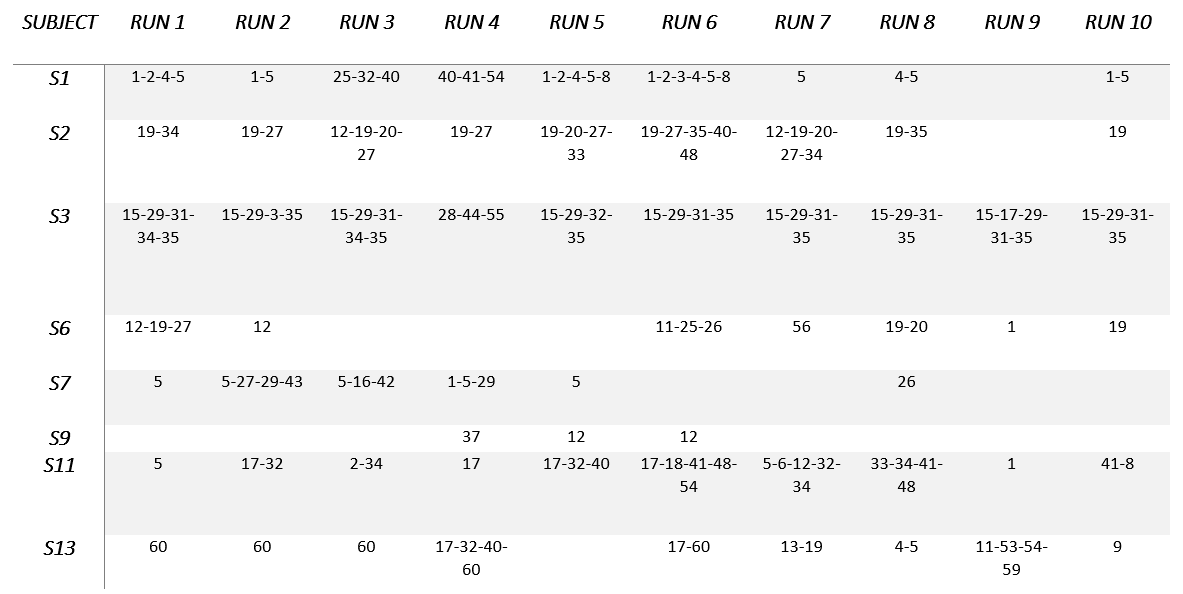

*Table 1: Bad channels witthout ICA application*

As can be observed in the table above, the channels for each run for each subject considered “bad channels” are shown. The cells with no “bad channel” are empty (-). It is important to mention that each channel has associated a label which determine the EEG electrode position. Some subjects may seem more interesting to take a second to mention on as for instance the subject number 9 which has almost no “bad channels” revealing that artifacts were not recorded. Also, subject number 3 shows some channels that are repeated in almost all the runs or a more heterogeneous distribution of bad channels during the different runs as subject 11 or subject 13. 

This time, the channels that were not eliminated for any run or subject were channels 7, 10, 14, 15, 21, 22, 23, 24, 30, 36, 38, 39, 45, 46, 47, 49, 50, 51, 52, 57, 58, and 61. 

In the table above, the bad channels resulting from the signal obtained when removing components with ICA are shown. In this first iteration, the threshold selected for component removal was too low (50% for the eye components and around 70% for the rest). A graph showing this is presented in the conclusions. Applying a such a low threshold, some of the important features of our solution get eliminated, thus directly affecting the possible analysis that can be performed. 

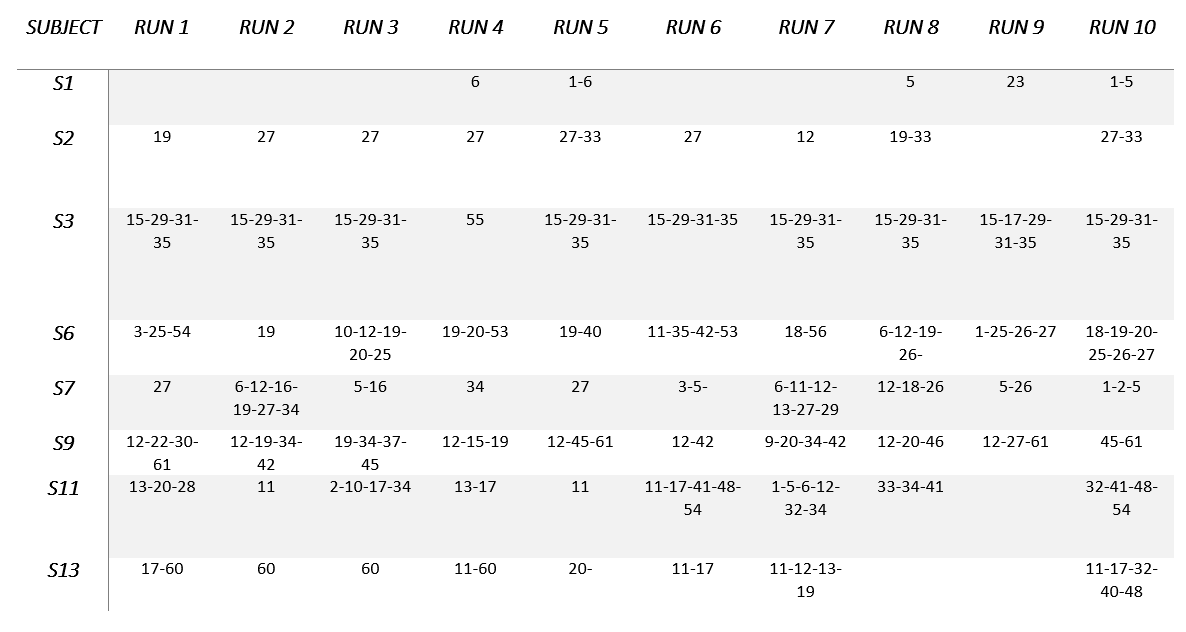

*Table 2: Bad channels with ICA, threshold for removal 50%*

It can be interesting to mention that there are some channels that have never been considered "bad channels" for any run and subject, which, more precisely, are channels 4, 7, 8, 14, 21, 24, 36, 38, 39, 43, 44, 47, 49, 50, 51, 52, 57, 58, and 59. 

In this second iteration, the threshold used for removing components with ICA was rised up until 85%. 

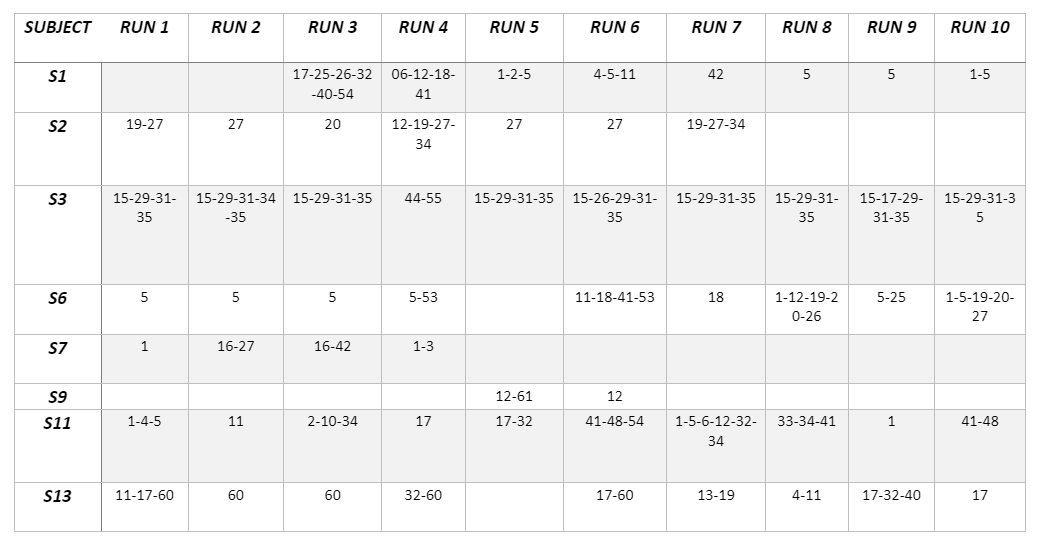

*Table 3: Bad channels with ICA, threshold for removal 85%*

It can be interesting to mention that there are some channels that have never been considered "bad channels" for any run and subject, which, more precisely, are channels 7, 8, 9, 14, 21, 22, 23, 24, 28, 30, 36, 37, 38, 39, 43, 45, 46, 47, 49, 50, 51, 52, 56, 57, 58 and 59

**2) Rejection of bad trials for each movement and subject**

Once the bad channels have been selected, we run the second function to find the bad trials. It takes the movement code as an argument, so we run it for each movement. In this case, the movement classes are:

- Flexion (1536)

- Open hand (1541)

Below, the different runs for the bad trials, with the different arguments, are coded. The variations calculated have been done with and without ICA and with and without automatic movement detection, in all of the possible permutations, thus yielding four different solutions for each movement type.

[ms_36_ica_auto,gm_36_ica_auto]=d2_bad_trials(subject_list,1536,true,true,data,icadata,resfolder);

The average difference with respect to the provided events is: -0.0014689s
Elapsed time is 3 minutes and 32.6386 seconds


[ms_36_auto,gm_36_auto]=d2_bad_trials(subject_list,1536,false,true,data,icadata,resfolder);

The average difference with respect to the provided events is: -0.0014689s
Elapsed time is 4 minutes and 10.4818 seconds


[ms_36_ica,gm_36_ica]=d2_bad_trials(subject_list,1536,true,false,data,icadata,resfolder);

Elapsed time is 2 minutes and 26.7869 seconds


[ms_36,gm_36]=d2_bad_trials(subject_list,1536,false,false,data,icadata,resfolder);

Elapsed time is 2 minutes and 39.1804 seconds


[ms_41_ica_auto,gm_41_ica_auto]=d2_bad_trials(subject_list,1541,true,true,data,icadata,resfolder);

The average difference with respect to the provided events is: -0.0019979s
Elapsed time is 3 minutes and 41.3567 seconds


[ms_41_auto,gm_41_auto]=d2_bad_trials(subject_list,1541,false,true,data,icadata,resfolder);

The average difference with respect to the provided events is: -0.0019979s
Elapsed time is 3 minutes and 55.5421 seconds


[ms_41_ica,gm_41_ica]=d2_bad_trials(subject_list,1541,true,false,data,icadata,resfolder);

Elapsed time is 2 minutes and 7.3861 seconds


[ms_41,gm_41]=d2_bad_trials(subject_list,1541,false,false,data,icadata,resfolder);

Elapsed time is 2 minutes and 37.0806 seconds


We have also chosen to show how long the calculations take, considering that the amount of data is not insignificant and thus, a good run time is desired.

## D2. Percentage of good (artifact-free) trials for each subject and movement class

- **Without ICA and without automatic movement detection**

Now we will want to display the data. If the variables are not loaded, we will load them from the file created in the previous step.

create_table(1:61,[false,false],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         90.96           97.08    
    S2         91.42           89.86    
    S3         96.37           98.25    
    S6         90.66           90.63    
    S7         93.77           95.63    
    S9         85.33            92.3    
    S11        93.11           93.17    
    S13         95.9           83.06    



Next, we create a table with the percentage of good trials for all channels. Considering we saved the bad trials and runs as NaNs, the following form creates and displays a table in Matlab's table format. On this occasion, the results in the table below are considering all channels. 

In the table above, the percentage of artifact-free trials for each subject can be seen for each movement class. Regarding elbow flexion, subject 2 is presents a lower rate of artifact-free trials, while subject 7 presents the best result. On the other hand, with regards to hand opening, subject 13 presents a lower percentage while subject 9 presents a higher percentage of artifact-free trials. 

- **With reduction of contamination by ICA**

create_table(1:61,[true,false],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         93.47           98.52    
    S2          92.6           88.17    
    S3         95.19           95.57    
    S6          86.5           87.76    
    S7         91.72           96.56    
    S9          80.6            85.9    
    S11        91.07            95.3    
    S13        88.69           93.22    



- **With automatic detection of movement onset**

create_table(1:61,[false,true],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         95.93           97.08    
    S2         88.11           89.86    
    S3         96.37           98.25    
    S6         90.66           90.63    
    S7         95.44           95.63    
    S9         91.83            92.3    
    S11        93.11           93.17    
    S13         95.9           83.06    



- **With automatic detection of movement onset and with reduction of contamination by ICA**

create_table(1:61,[true,true],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         98.47           98.52    
    S2         89.62           88.14    
    S3         95.19           95.57    
    S6          86.5           87.76    
    S7         93.39           96.56    
    S9         86.86            85.9    
    S11        90.82            95.3    
    S13        88.69           93.22    



Then we create a table for **Cz (channel 30)** only, in order to compare our results with the provided example.

- **Without ICA and without automatic movement detection**

%esto no entendemos muy bien por qué cuando canal 1 (f3) no se corresponde
%el s1 con el que nos dan
create_table(1,[false,false],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1            90           96.67    
    S2         51.67           46.67    
    S3         91.67           98.33    
    S6         41.67           36.67    
    S7         83.33              85    
    S9         58.33              50    
    S11        93.33              90    
    S13           80           71.67    



Although for hand opening, both results are almost the same, subject 3 has a slightly higher good trial rate in the provided data. This could be due to the filtering and processing methodology, and was therefore not considered to be an issue.

- **With reduction of contamination by ICA**

create_table(30,[true,false],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         93.33             100    
    S2            95           91.67    
    S3            95           96.67    
    S6         91.67           93.33    
    S7         93.33           96.67    
    S9         83.33              90    
    S11        91.67              95    
    S13           90              95    



- **With automatic detection of movement onset**

create_table(30,[false,true],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         96.67           96.67    
    S2            90           91.67    
    S3         98.33           98.33    
    S6         96.67           98.33    
    S7         96.67           96.67    
    S9         91.67           96.67    
    S11        93.33              95    
    S13        98.33              85    



- **With automatic detection of movement onset and with reduction of contamination by ICA**

create_table(30,[true,true],subject_list)

           Elbow Flexion    Hand Opening
           _____________    ____________

    S1         98.33             100    
    S2         91.67           91.67    
    S3            95           96.67    
    S6         91.67           93.33    
    S7            95           96.67    
    S9            90              90    
    S11        91.67              95    
    S13           90              95    



## D3. Plots

In this section, the average (considering only the good trials) for channel Cz for each subject and class movement has been represented. Moreover, the grand-mean average (average of all subjects) of trials for Cz and each movement class.

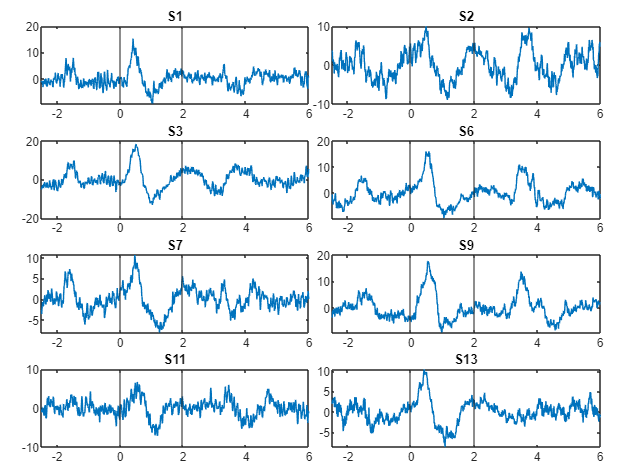

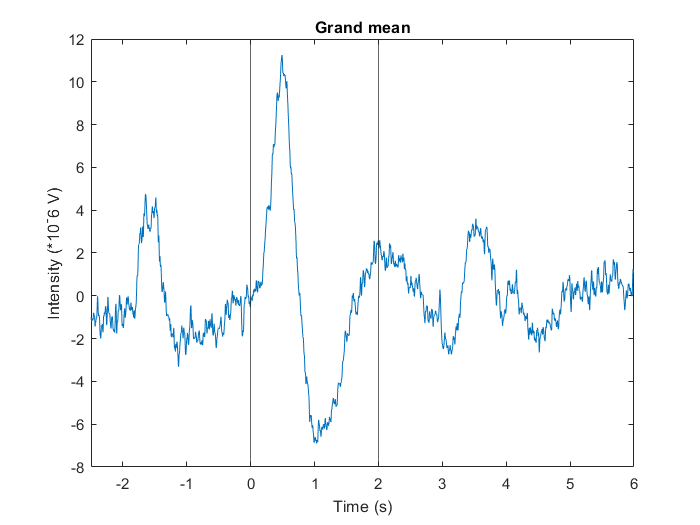

make_plots(ms_36,30,gm_36,30,subject_list)

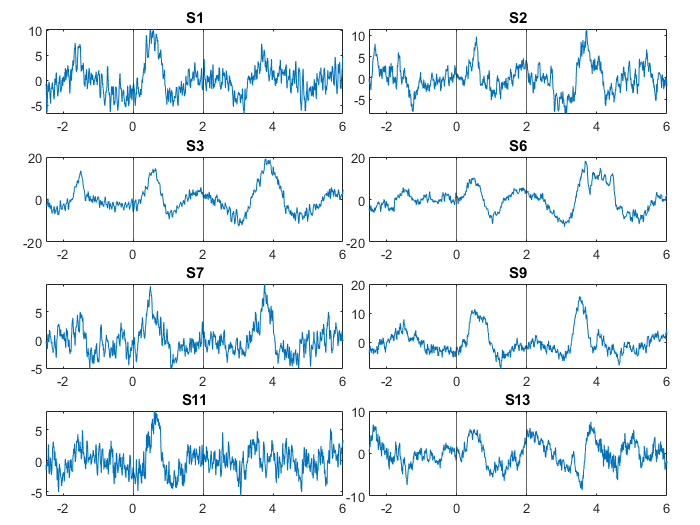

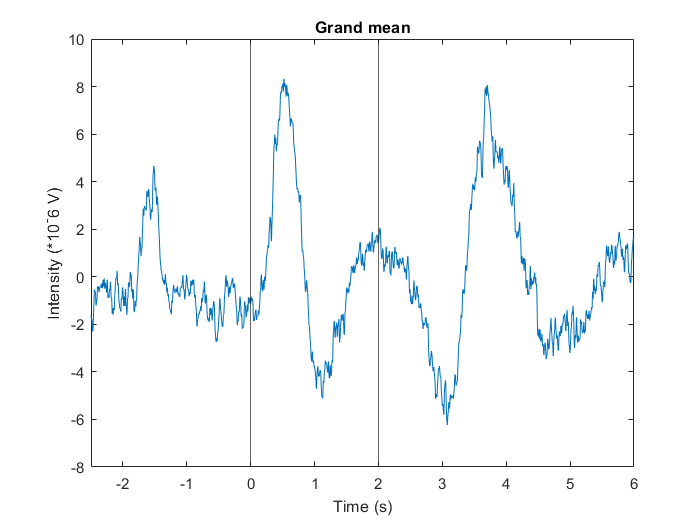

make_plots(ms_41,30,gm_41,30,subject_list)

**WITH ICA**

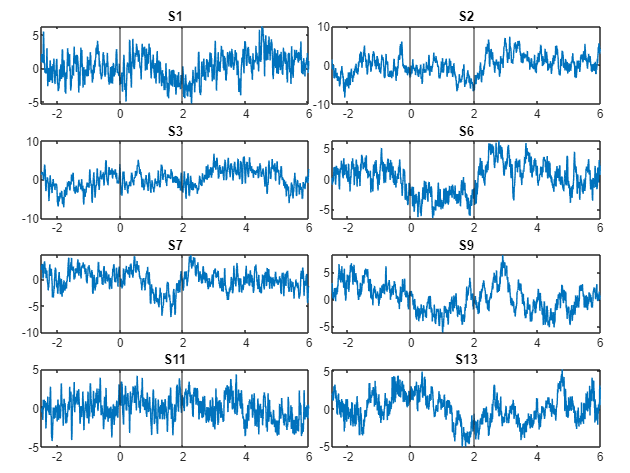

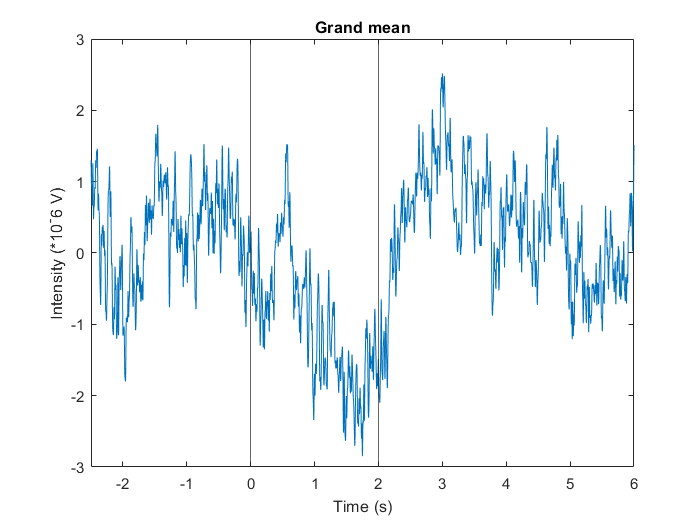

make_plots(ms_36_ica,30,gm_36_ica,30,subject_list)

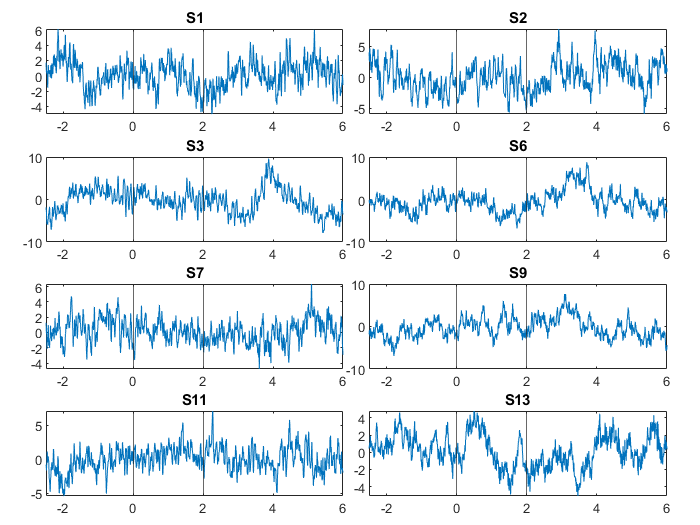

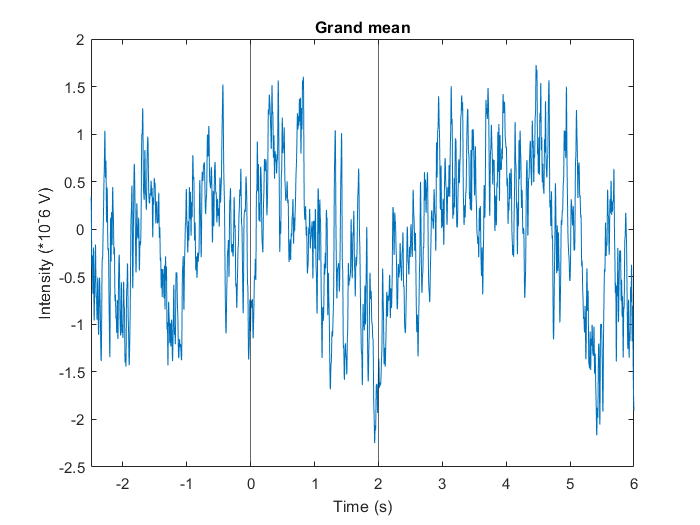

make_plots(ms_41_ica,30,gm_41_ica,30,subject_list)

**WITH AUTO**

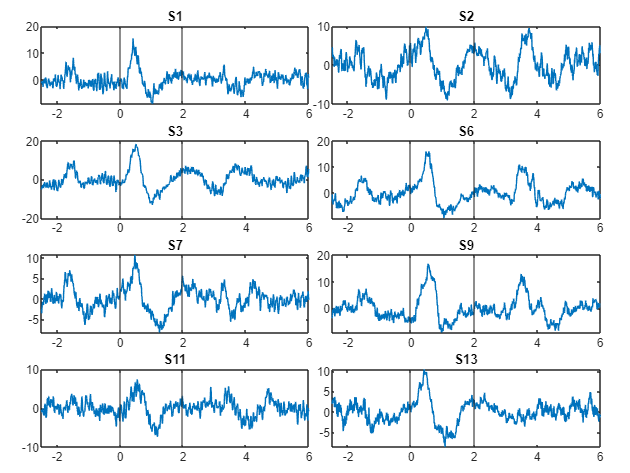

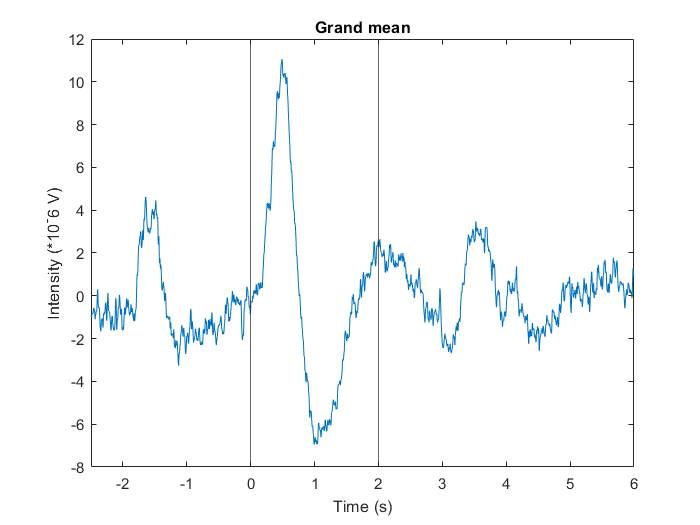

make_plots(ms_36_auto,30,gm_36_auto,30,subject_list)

make_plots(ms_41_auto,30,gm_41_auto,30,subject_list)

**WITH ICA _ WITH AUTO**

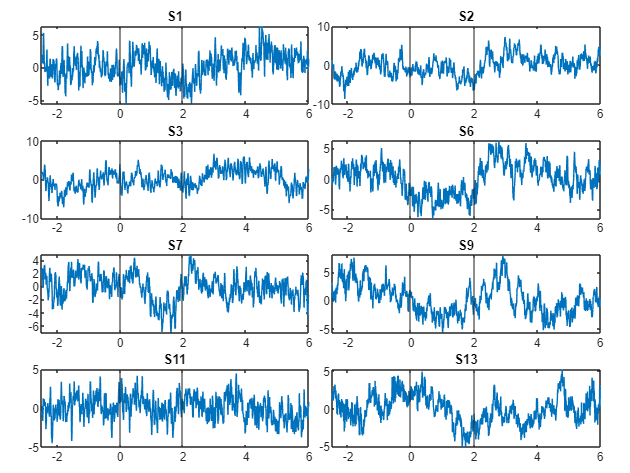

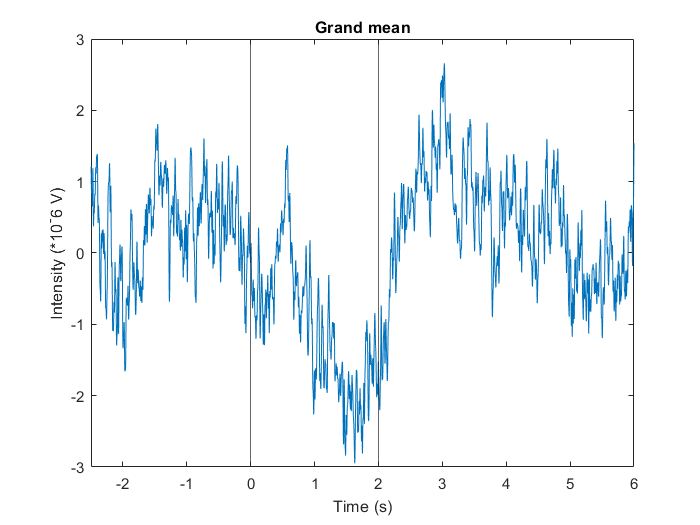

make_plots(ms_36_ica_auto,30,gm_36_ica_auto,30,subject_list)

make_plots(ms_41_ica_auto,30,gm_41_ica_auto,30,subject_list)


ho_30 = mean_all_files(1541,[false,false],subject_list,data,icadata)

Dot indexing is not supported for variables of this type.

Error in mean_all_files (line 68)
                sr=sr.filtered_data(:,:);


ho_30=squeeze(mean(bad_trials_1541(30,:,:,:),3,'omitnan'));
ef_30=squeeze(mean(bad_trials_1536(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_ica.mat");
ica1541=load("bad_trials_1541_with_ica.mat");

ho_30_ica=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));
fm=512;
t=-0.5+1/fm:1/fm:(4352-0.5*512)/fm;
figure(6)
nt=tiledlayout('flow','TileSpacing','compact','Padding','compact');
for i=1:8

    nexttile
    hold on
    plot(t,ho_30(:,i))
    plot(t,ho_30_ica(:,i))  
    xline(0)
    xline(2)
    xlim([-0.5 8])
    hold off
    title(subject_list(i))

    
end
xlabel(nt,'seconds')
    ylabel(nt,'µV')
    legend('Normal','ICA',"Position",[0.67677,0.2398,0.15,0.072619])

Above, we can see that, in general, we can distinguish a relatively clear stimulus response right after the initial stimulus, followed by the reaction, which happens after 2 seconds. This is what was expected, and happens for both the ICA trated and the normally processed data. Interestingly these two are not so different, and are most clearly distinguishable in subjects that have cleaner data, such as subjects 3 and 6. We can see that the non-potential related areas are flattened by the ICA procedure.

figure
t_l=tiledlayout('flow','TileSpacing','compact','Padding','compact');
for i=1:8

    nexttile
    hold on
    plot(t,ef_30(:,i))
    plot(t,ef_30_ica(:,i))
    xline(0)
    xline(2)
    xlim([-0.5 8])
    hold off
    title(subject_list(i))
    
end
xlabel(t_l,'seconds')
ylabel(t_l,'µV')
legend('Normal','ICA',"Position",[0.67677,0.2398,0.15,0.072619])

The elbow flexion movement shows no large differences when compared to hand opening movement. Perhaps, the first peak is slightly more defined while the second peak less so, but mostly, the graphs look similar. Patients 3,6 and 9 seem to have cleaner signals, indicating that perhaps, they are bald.

ica1536=load("bad_trials_1536_with_ica_with_auto.mat");
ica1541=load("bad_trials_1541_with_ica_with_auto.mat");

ho_30_ica_auto=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica_auto=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

ica1536=load("bad_trials_1536_with_auto.mat");
ica1541=load("bad_trials_1541_with_auto.mat");

ho_30_auto=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_auto=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

gm_average_30_ho=mean(ho_30,2);
gm_30_ica_ho=mean(ho_30_ica,2);
gm_30_ho_auto=mean(ho_30_auto,2);
gm_30_ica_auto_ho=mean(ho_30_ica_auto,2);

figure
plot(t,gm_average_30_ho)
hold on
plot(t,gm_30_ica_ho)
plot(t,gm_30_ho_auto,'--')
plot(t,gm_30_ica_auto_ho,'--')
xline(2)
xline(0)
xlim([-0.5 8])
legend('Normal','ICA','Auto detect','ICA + Auto')
xlabel('seconds')
ylabel('µV')

hold off

Above, the graph depicts the grand mean average for hand opening in all 4 evaluated variations. If the movement is automatically detected, the resulting data does not differ much from the original data. This was to be expected, since the average time difference between the provided and calculated values was in the range of 1-2ms. The resulting bad trials are thus very similar and differ only very slightly.

We can see that the grand mean average provides a clean idea of what the locked stimulus looks like. Interestingly, performing an ICA to remove undesirable components seems to affect the amplitude of the peaks and also affect how constant the other parts of the signal are.

gm_average_30_ef=mean(ef_30,2);
gm_30_ica_ef=mean(ef_30_ica,2);
gm_30_ef_auto=mean(ef_30_auto,2);
gm_30_ica_auto_ef=mean(ef_30_ica_auto,2);

figure
plot(t,gm_average_30_ef)
hold on
plot(t,gm_30_ica_ef)
plot(t,gm_30_ef_auto,'--')
plot(t,gm_30_ica_auto_ef,'--')
xline(2)
xline(0)
xlim([-0.5 8])
legend('Normal','ICA','Auto detect','ICA + Auto')
xlabel('seconds')
ylabel('µV')

hold off

With the elbow flexion trial, the ICA effect becomes more clear: it is removing the baseling and is giving a signal that stays closer to average when there is no activity peak. Otherwise, there are other particularities about this grand mean average. For one, the second large peak at 6 seconds is no longer as large as the first. Also, the trough between 3 and 5 seconds has a ocmpletely different shape, which is hard to attribute to electrode placement, and might be understood as the consequence of a smaller cortical representation of the elbow in comparison to the hand, but channel 30 (Cz) is closer to this electrode. How and why this affects the signal is not clear. It might only explain why the amplitude of the elbow movement is somewhat larger.

% for doing this part, "bad_trials_1536_with_ica_acsobi.mat" is needed, 
% thus the eeglab code must be run with the acsobi algorithm and rename the variable. 

ica1536=load("bad_trials_1536_with_ica_acsobi.mat");
ica1541=load("bad_trials_1541_with_ica_acsobi.mat");

ho_30_ica_acsobi=squeeze(mean(ica1541.matrix_detrend(30,:,:,:),3,'omitnan'));
ef_30_ica_acsobi=squeeze(mean(ica1536.matrix_detrend(30,:,:,:),3,'omitnan'));

gm_30_ica_ho_acsobi=mean(ho_30_ica_acsobi,2);
gm_30_ica_ef_acsobi=mean(ef_30_ica_acsobi,2);

figure
plot(t,gm_30_ica_ho)
hold on
plot(t,gm_30_ica_ho_acsobi)
xline(2)
xline(0)
xlim([-0.5 8])
legend('Sobi','Acsobi')
xlabel('seconds')
ylabel('µV')

hold off

For the purposes of completeness, and since we have evaluated the data with both ICA decomposition types, we have decided to show the difference between the calculations made with the 'sobi' algorithm and the 'acsobiro' algorithm. Indeed, there is a difference between the two, but it is clear that it is a small difference.

figure
plot(t,gm_30_ica_ef)
hold on
plot(t,gm_30_ica_ef_acsobi)
xline(2)
xline(0)
xlim([-0.5 8])
legend('Sobi','Acsobi')
xlabel('seconds')
ylabel('µV')

hold off

As above, we show the difference between both algorithms, this time for the elbow flexion movement.

**Conclusions**

In this preprocessing section, firstly, we have selected the bad channels by both heuristic criteria and an additional elimination of components by ICA algorithms. Then, we have proceded to select and mark the bad trials in the data, also by heuristic and statistic criteria, both with automatic movement detection as well as with the provided movement data. Finally, we have visualized the obtained data.

During this process, firstly, we looked at the signal and realized that there were multiple eye artifacts. After cleaning the signal, it had improved greatly, but the eye components were not removed effectively. On the other hand, an ICA decomposition helped with the horizontal eye movements, but was not able to separate the eye components from the brain components for blinks. Other artifacts that were removed with ICA were line noise, channel noise, muscle, heart and "other". These were only removed if the IClabel algorithm calculated that there was an 85% probability or higher that they belonged to this group. This threshold was chosen after trying a 50% for eyes and a 70% threshold for the rest of the groups. This yielded different results, which can be seen below:

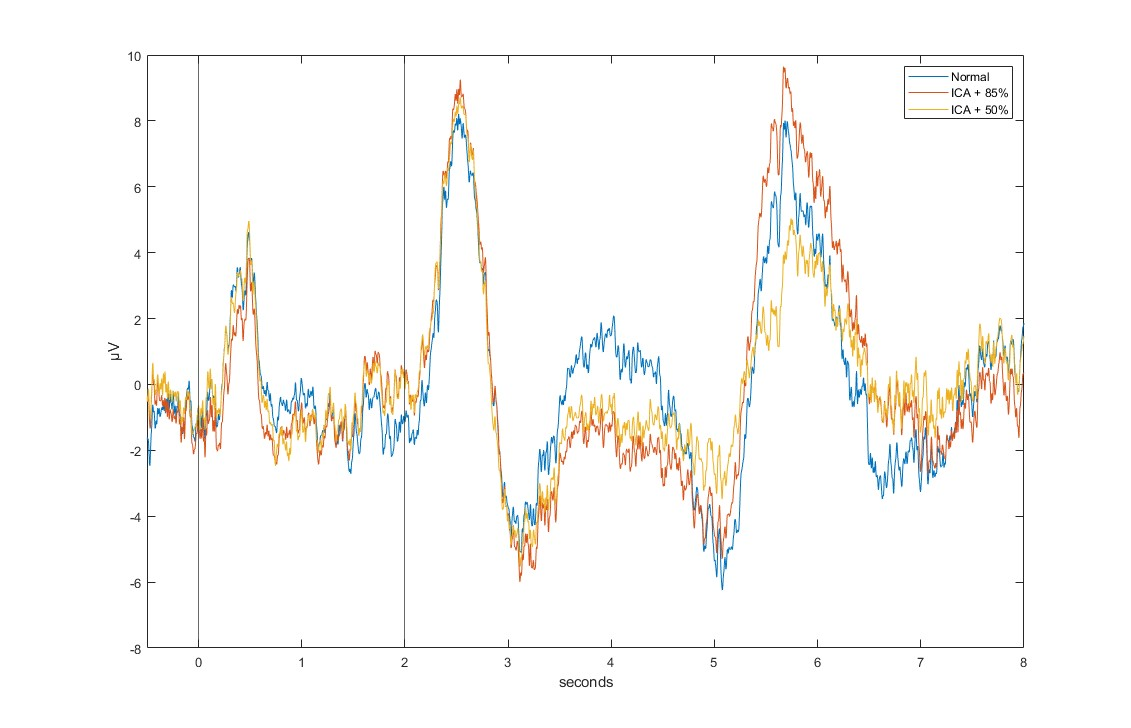

The main difference can be seen in the second peak and the trough right before it, which, when the threshold is higher, is more similar to the original signal.

The movement detection algorithm also yielded interesting results, which were corroborated manually in order to establish their accuracy. They were found to be more accurate than the provided data. Consequently, the good trial percentage differed slightly from the one we saw in the example, but was considered to be quite similar and thus satisfactory. 

Finally, the section in which we plotted the results portrayed the difficulty of visualizing differences even with large numbers of trials. It was only in the a few subjects, and especially with the grand mean average, that the general trends became more clear, and the signal became cleaner. The high variance of EEG signals, as well as the difficulty in obtaining very large datasets, makes it clear that very good signal processing is necessary in this field.

In a future version of this script, we have considered improving the way in which we save our data. Most of the run time of our script, particularly, the bad trial calculation, comes from loading very large files created in the first section. This could potentially be avoided by working with cell arrays or struct files, which would probably reduce running time by about 1 hour, by our estimations.